G = tf([1],[1 4])


G =
 
    1
  -----
  s + 4
 
Continuous-time transfer function.



s = tf('s');
G2 = 1 / (s+4)


G2 =
 
    1
  -----
  s + 4
 
Continuous-time transfer function.



G3 = zpk([],[-4],1)


G3 =
 
    1
  -----
  (s+4)
 
Continuous-time zero/pole/gain model.



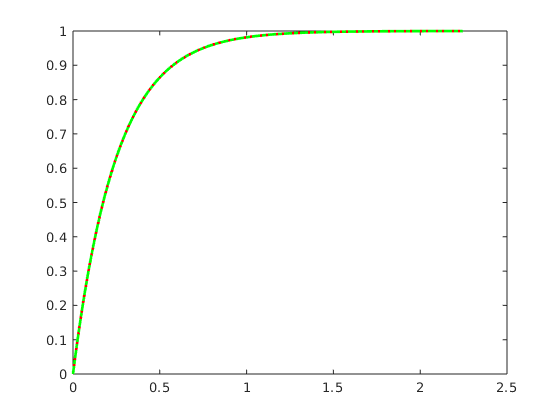

[y1, t1] = step(4*G);
[y2, t2] = step(4*G2);
[y3, t3] = step(4*G3);
plot(t1,y1,'r-',t2,y2,'b--',t3,y3,'g-.','LineWidth',2)